m = 56;
n = 64;
k = 3;
SNR = 30;
tol = 0;
c = 1;
search_iter = 50;
lower = 0;
upper = 2^k - 1;
%Generate system
[A, x_t, y, ~, permutation, ~] = gen_ublm_problem(k, m, n, SNR, c, search_iter);

tol = 5.0088


%initial point CGSIC:
[x_hat, A_hat, P] = cgsic(A, y, lower, upper);
norm(y-A*x_t)

ans = 5.0058

x_t'

ans =      5     5     5     0     6     5     5     6     5     4     0     4     5     2     0     7     3     0     4     4     4     6     1     4     2     7     4     6     0     6     2     6     3     1     5     6     6     7     7     2     3     1     2     2     4     2     2     3     0     0



sum(x_t)

ans = 231

%search_iter = factorial(6); %10;
%Determine threshold
% if threshold
%     tol = sqrt(m * sigma_squared);
% else
%     tol = 0;
% end

A

A =    -2.1149   -3.2938   -0.1024   -1.4758    2.5738   -0.4568    1.2281   -1.3429   -5.3106   -0.7464   -0.4222   -2.8198    1.5071   -0.3150    1.7911    2.1395   -1.2861   -2.6716    1.4018   -1.0361    0.3805    0.1513   -1.5854    4.6553   -2.4233   -0.9071    0.7581   -1.3476    0.8386    2.0773    0.0883    3.0091   -1.0816   -2.5228   -1.6197    1.7353   -1.2245   -0.6154   -0.2663    0.4078    1.1959   -1.2048    1.6575    0.5138    0.4488    0.8113   -0.5298    0.9248    3.2754    3.5992
   -3.3405    2.0712   -1.7162    0.1181    1.4877    0.4377    3.0103    2.7054   -0.6466   -4.0368    1.0815    1.1784    1.2269   -3.3444    2.1751   -1.8595   -2.4369   -1.9655    2.0623   -2.2537    0.1646    0.6595    1.3494    0.5273   -0.3617    2.4458   -0.1045    2.3708    0.0350    3.0164    0.5148    2.4770    2.7571    0.6408   -0.4177    0.8068   -0.7061    2.2695    0.0845   -0.5385   -1.2796   -1.3964    3.8829    1.9521   -2.9823    0.2272   -4.3581   -0.9244    3.2405    0

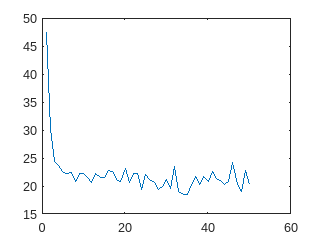

% % SCP-Blocm Babai
% tic;
% [s_bar_cur, rhos] = bsic(x_hat, inf, A, tol, search_iter, y, k, permutation, true);
% plot(1:search_iter, rhos)
% s_bar_cur'
% sum(s_bar_cur)
% %SCP-Blocm Optimal
[s_bar_cur, rhos] = bsic(x_hat, inf, A, tol, search_iter, y, k, permutation, false);
plot(1:search_iter, rhos)

s_bar_cur'

ans =      5     7     2     1     5     6     5     7     4     2     2     2     6     6     0     7     1     0     6     6     4     5     1     3     3     7     4     5     0     3     3     6     3     0     3     5     7     7     6     3     4     0     2     0     4     4     0     3     0     1


sum(s_bar_cur)

ans = 233

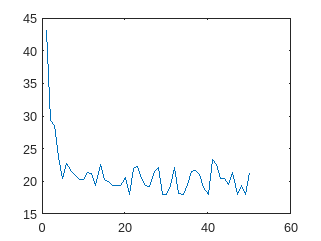


[s_bar_cur, rhos] = bsic(x_hat, inf, A, tol, search_iter, y, k, permutation, true);
plot(1:search_iter, rhos)

s_bar_cur'

ans =      5     6     2     1     5     7     5     7     4     2     1     2     5     5     0     7     1     0     5     5     3     6     1     3     3     6     3     6     0     4     3     6     3     0     4     5     7     7     6     3     3     0     2     0     3     4     1     3     0     1


sum(s_bar_cur)

ans = 228

% %SCP-Blocm Optimal




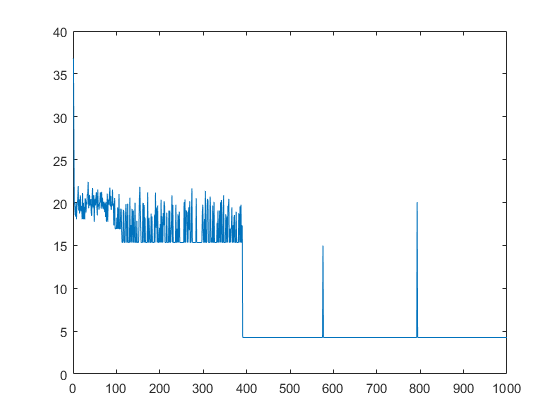

plot(1:search_iter, rhos)

56x64

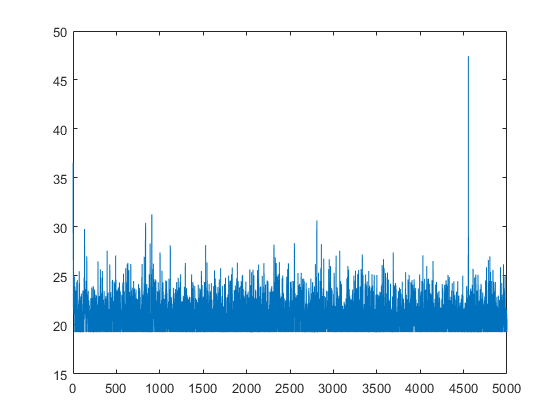

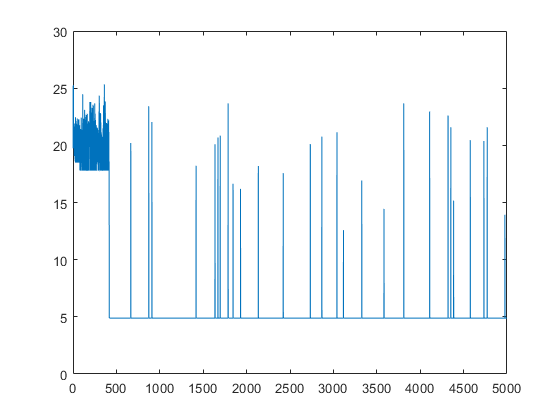

32x64